clearvars
syms P_c E_1 E_2 delta_r c nu_1 nu_2 k_1 k_2 r L T mu_s delta_tol real positive
syms sigma_1 sigma_2 sigma_3 sigma_vm sigma sigma_r sigma_theta tau_r_theta real
assumeAlso(k_1 > 1)
assumeAlso(k_2 > 1)
assumeAlso(nu_1 < 1)
r_1o = sym('r_1_o', {'real', 'positive'});
r_1i = sym('r_1_i', {'real', 'positive'});
r_2o = sym('r_2_o', {'real', 'positive'});
r_2i = sym('r_2_i', {'real', 'positive'});
assumeAlso(r_2i < r_2o)
assumeAlso(c < r_2o)
digits(3);
u = symunit;

# Interference Fits

One method of transferring power from a shaft to a component mounted on the shaft is through frictional forces generated from an interference fit.

An interference fit is where the shaft is very slightly larger than the bore in the component. This results in the shaft shrinking slightly and the external component expanding slightly when assembled.

The greater the interference, the greater the frictional forces (and allowable torque before the component slips), but also greater hoop stresses resulting in failure.

## Governing Equations in Interference

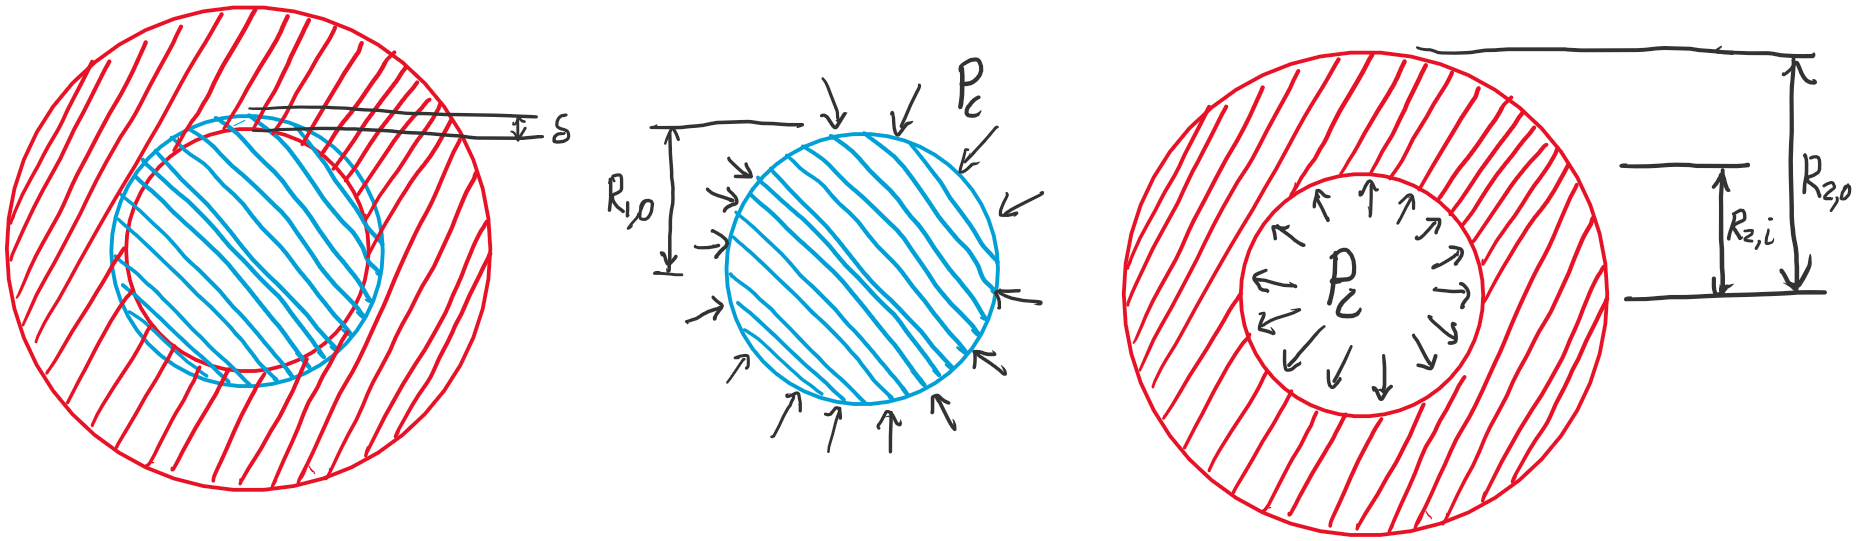

The relationship between interfacial pressure $P_c$ and the shaft and component properties is given below:

eqInterference = delta_r/c == P_c/E_1*((k_1^2+1)/(k_1^2-1)-nu_1) + P_c/E_2*((k_2^2+1)/(k_2^2-1)+nu_2)

$$eqInterference = \frac{\delta_{r}}{c}=\frac{P_{c}\,\left(\nu_{2}+\frac{{k_{2}}^{2}+1}{{k_{2}}^{2}-1}\right)}{E_{2}}-\frac{P_{c}\,\left(\nu_{1}-\frac{{k_{1}}^{2}+1}{{k_{1}}^{2}-1}\right)}{E_{1}}$$

eqK1 = k_1 == r_1o/r_1i

$$eqK1 = k_{1}=\frac{r_{1,o}}{r_{1,i}}$$

eqK2 = k_2 == r_2o/r_2i

$$eqK2 = k_{2}=\frac{r_{2,o}}{r_{2,i}}$$

eqCommon = c == r_1o

$$eqCommon = c=r_{1,o}$$

## Required Interfacial Pressure

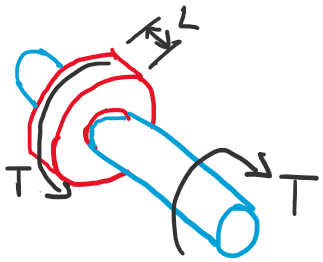

### Minimum Interfacial Pressure

We can calculate the minimum required Interfacial Pressure $P_c$ from the torque $T$ based on the friction between the two materials

eqMinPressure = P_c*L*2*pi*c*mu_s == T/c;
eqMinPressure = isolate(eqMinPressure,P_c)

$$eqMinPressure = P_{c}=\frac{T}{2\,L\,c^{2}\,\mu_{s}\,\pi }$$

values = {
r_1i, 0*u.mm
r_1o, 1*u.mm
r_2i, 1*u.mm
r_2o, 3.73/2*u.mm
mu_s, 0.3
sigma_vm, 600*u.MPa
T, 134.5*u.N*u.mm
L, 4.5*u.mm
c, 1*u.mm
E_1, 207*u.GPa
nu_1, 0.3
}

values = 11×2 cell array
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {[0.3000]}
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {1×1 sym }
    {1×1 sym}    {[0.3000]}


unitConvert(vpa(subs(eqMinPressure,values(:,1),values(:,2))),u.MPa)

$$ans = P_{c}=15.9\,\mathrm{MPa}$$

### Maximum Interfacial Pressure

We can also calculate the maximum allowable Interfacial Pressure before the gear fails in yield (as hoop stresses are likely to be much higher in the bore of the gear) according to the Von Mises failure criterion

eqVonMises = 2*sigma_vm^2 == (sigma_1-sigma_2)^2+(sigma_2-sigma_3)^2+(sigma_3-sigma_1)^2

$$eqVonMises = 2\,{\sigma_{\mathrm{vm}}}^{2}={\left(\sigma_{1}-\sigma_{2}\right)}^{2}+{\left(\sigma_{1}-\sigma_{3}\right)}^{2}+{\left(\sigma_{2}-\sigma_{3}\right)}^{2}$$

eqPrincipal1 = sigma_1 == (sigma_r+sigma_theta)/2 + sqrt(((sigma_r-sigma_theta)/2)^2+tau_r_theta^2)

$$eqPrincipal1 = \sigma_{1}=\frac{\sigma_{r}}{2}+\frac{\sigma_{\theta }}{2}+\sqrt{{\left(\frac{\sigma_{r}}{2}-\frac{\sigma_{\theta }}{2}\right)}^{2}+{\tau_{r,\theta }}^{2}}$$

eqPrincipal2 = sigma_2 == (sigma_r+sigma_theta)/2 - sqrt(((sigma_r-sigma_theta)/2)^2+tau_r_theta^2)

$$eqPrincipal2 = \sigma_{2}=\frac{\sigma_{r}}{2}+\frac{\sigma_{\theta }}{2}-\sqrt{{\left(\frac{\sigma_{r}}{2}-\frac{\sigma_{\theta }}{2}\right)}^{2}+{\tau_{r,\theta }}^{2}}$$

Substituting the principal stresses into the von mises equation, and assuming $\sigma_3 = 0$ (plane stress), we get the following:

eqVonMises = subs(eqVonMises,{lhs(eqPrincipal1),lhs(eqPrincipal2),sigma_3},{rhs(eqPrincipal1),rhs(eqPrincipal2),0});
eqVonMises = isolate(simplify(eqVonMises),sigma_vm)

$$eqVonMises = \sigma_{\mathrm{vm}}=\sqrt{{\sigma_{r}}^{2}-\sigma_{r}\,\sigma_{\theta }+{\sigma_{\theta }}^{2}+3\,{\tau_{r,\theta }}^{2}}$$

The radial stress at the bore $\sigma_r$ is the **negative** of interfacial pressure $P_c$  


$$\sigma_r = -P_c$$
 

The hoop stress at the bore $\sigma_\theta$ is calculated from the following Lamé equation:

eqHoop = sigma_theta == P_c/(k_2^2-1)*(1+r_2o^2/r^2)

$$eqHoop = \sigma_{\theta }=\frac{P_{c}\,\left(\frac{{r_{2,o}}^{2}}{r^{2}}+1\right)}{{k_{2}}^{2}-1}$$

eqHoopBore = subs(eqHoop, r, r_2i);
eqHoopBore = subs(eqHoopBore,rhs(eqK2),lhs(eqK2))

$$eqHoopBore = \sigma_{\theta }=\frac{P_{c}\,\left({k_{2}}^{2}+1\right)}{{k_{2}}^{2}-1}$$

The shear stress is calculated from the torque, (which we'll assume increases to what will cause slip at the maximum $P_c$ 

eqShear = tau_r_theta*c*2*pi*c*L == T

$$eqShear = 2\,\pi \,L\,c^{2}\,\tau_{r,\theta }=T$$

eqShear = subs(eqMinPressure,rhs(eqShear),lhs(eqShear));
eqShear = isolate(eqShear, tau_r_theta)

$$eqShear = \tau_{r,\theta }=P_{c}\,\mu_{s}$$

Substituting the equations for $\tau_{r,\theta}$, $\sigma_r$, $\sigma_\theta$ into the von Mises equation gives us the following:

eqVonMises

$$eqVonMises = \sigma_{\mathrm{vm}}=\sqrt{{\sigma_{r}}^{2}-\sigma_{r}\,\sigma_{\theta }+{\sigma_{\theta }}^{2}+3\,{\tau_{r,\theta }}^{2}}$$

eqMaxPressure = subs(eqVonMises, {lhs(eqHoopBore),sigma_r, lhs(eqShear)},{rhs(eqHoopBore),-P_c,rhs(eqShear)})

$$eqMaxPressure = \sigma_{\mathrm{vm}}=\sqrt{{P_{c}}^{2}+3\,{P_{c}}^{2}\,{\mu_{s}}^{2}+\frac{{P_{c}}^{2}\,{\left({k_{2}}^{2}+1\right)}^{2}}{{\left({k_{2}}^{2}-1\right)}^{2}}+\frac{{P_{c}}^{2}\,\left({k_{2}}^{2}+1\right)}{{k_{2}}^{2}-1}}$$

Rearranging for $P_c$ gives us the following equation in terms of the radii:

eqMaxPressure = simplify(isolate(eqMaxPressure,P_c));

eqMaxPressure = subs(eqMaxPressure,lhs(eqK2),rhs(eqK2))

$$eqMaxPressure = P_{c}=\frac{\sigma_{\mathrm{vm}}\,\left(\frac{r_{2,o}}{r_{2,i}}-1\right)\,\left(\frac{r_{2,o}}{r_{2,i}}+1\right)}{\sqrt{\frac{3\,{r_{2,o}}^{4}}{{r_{2,i}}^{4}}+3\,{\mu_{s}}^{2}-\frac{6\,{\mu_{s}}^{2}\,{r_{2,o}}^{2}}{{r_{2,i}}^{2}}+\frac{3\,{\mu_{s}}^{2}\,{r_{2,o}}^{4}}{{r_{2,i}}^{4}}+1}}$$

Substituting the values for radii, friction and yield stress gives us the interfacial pressure that results in yielding:

vpa(subs(eqMaxPressure,values(:,1),values(:,2)))

$$ans = P_{c}=238.0\,\mathrm{MPa}$$

We can calculate the upper and lower bound of the radial interference from the two interfacial pressures, and find out if this is achievable given conventional machining processes. In this case, the shaft and gear materials are the same ($E_1 = E_2, \nu_1 = \nu_2$) so further simplifications can be made. In addition, we assume $c = r_{2,i} = r_{1,o}$ and $r_{1,i} = 0$

eqInterference

$$eqInterference = \frac{\delta_{r}}{c}=\frac{P_{c}\,\left(\nu_{2}+\frac{{k_{2}}^{2}+1}{{k_{2}}^{2}-1}\right)}{E_{2}}-\frac{P_{c}\,\left(\nu_{1}-\frac{{k_{1}}^{2}+1}{{k_{1}}^{2}-1}\right)}{E_{1}}$$

eqInterferenceSame = simplify(subs(eqInterference,{E_2,nu_2},{E_1,nu_1}));
eqInterferenceSame = simplify(subs(eqInterferenceSame,{lhs(eqK1),lhs(eqK2)},{rhs(eqK1),rhs(eqK2)}));
eqInterferenceSame = simplify(subs(eqInterferenceSame,{r_1o,r_2i,r_1i},{c,c,0}));
isolate(eqInterferenceSame,delta_r)

$$ans = \delta_{r}=-\frac{2\,P_{c}\,c\,{r_{2,o}}^{2}}{E_{1}\,c^{2}-E_{1}\,{r_{2,o}}^{2}}$$

Substituting the equation for the maximum interfacial pressure (when it results in yield), we get the following:

eqDeltaMax = simplify(subs(eqInterferenceSame,{lhs(eqMaxPressure)},{rhs(eqMaxPressure)}));
eqDeltaMax = subs(eqDeltaMax,r_2i,c);
eqDeltaMax = isolate(eqDeltaMax,delta_r)

$$eqDeltaMax = \delta_{r}=\frac{2\,c\,{r_{2,o}}^{2}\,\sigma_{\mathrm{vm}}}{E_{1}\,\sqrt{3\,c^{4}\,{\mu_{s}}^{2}+c^{4}-6\,c^{2}\,{\mu_{s}}^{2}\,{r_{2,o}}^{2}+3\,{\mu_{s}}^{2}\,{r_{2,o}}^{4}+3\,{r_{2,o}}^{4}}}$$

vpa(unitConvert(simplify(subs(eqDeltaMax,values(:,1),values(:,2))),u.um))

$$ans = \delta_{r}=3.23\,\mathrm{\mu m}$$

Substituting the equation for the Minimum interfacial pressure required (to prevent slippage when a torque is applied), we get the following:

eqDeltaMin = simplify(subs(eqInterferenceSame,lhs(eqMinPressure),rhs(eqMinPressure)));
eqDeltaMin = isolate(eqDeltaMin, delta_r)

$$eqDeltaMin = \delta_{r}=-\frac{T\,{r_{2,o}}^{2}}{E_{1}\,L\,c\,\mu_{s}\,\pi \,\left(c^{2}-{r_{2,o}}^{2}\right)}$$

vpa(unitConvert(simplify(subs(eqDeltaMin,values(:,1),values(:,2))),u.um))

$$ans = \delta_{r}=0.215\,\mathrm{\mu m}$$

## Optimising the Interface Radius to Maximise Tolerance

The above equations show that the bore and shaft have to be machined to extremely tight tolerances. By calculating the difference in the $\delta_r$, we can attempt to optimise $c$.

% replacing value of common radius c, with symbol, so it remains a function
% of c when values are substituted.
index = find([values{:,1}] == c);
values{index,2} = c*u.mm;
fDeltaMax(c) = rhs(eqDeltaMax)

$$fDeltaMax(c) = \frac{2\,c\,{r_{2,o}}^{2}\,\sigma_{\mathrm{vm}}}{E_{1}\,\sqrt{3\,c^{4}\,{\mu_{s}}^{2}+c^{4}-6\,c^{2}\,{\mu_{s}}^{2}\,{r_{2,o}}^{2}+3\,{\mu_{s}}^{2}\,{r_{2,o}}^{4}+3\,{r_{2,o}}^{4}}}$$

fDeltaMaxsubs = separateUnits(unitConvert(simplify(subs(fDeltaMax,values(:,1),values(:,2))),u.um))

$$fDeltaMaxsubs(c) = \frac{556516000\,c}{69\,\sqrt{203200000000\,c^{4}-300518640000\,c^{2}+6329699315607}}$$

fDeltaMin(c) = rhs(eqDeltaMin)

$$fDeltaMin(c) = -\frac{T\,{r_{2,o}}^{2}}{E_{1}\,L\,c\,\mu_{s}\,\pi \,\left(c^{2}-{r_{2,o}}^{2}\right)}$$

fDeltaMinsubs = separateUnits(unitConvert(simplify(subs(fDeltaMin,values(:,1),values(:,2))),u.um))

$$fDeltaMinsubs(c) = -\frac{374257010}{5589\,c\,\pi \,\left(40000\,c^{2}-139129\right)}$$

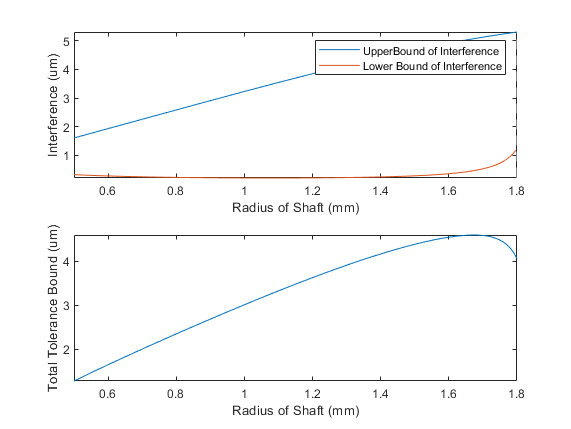

subplot(2,1,1)
fplot([fDeltaMaxsubs, fDeltaMinsubs],[0.5, 1.8])
legend('Upper Bound of Interference', 'Lower Bound of Interference')
xlabel('Radius of Shaft (mm)')
ylabel('Interference (um)')
subplot(2,1,2)
fplot(fDeltaMaxsubs-fDeltaMinsubs,[0.5, 1.8])
xlabel('Radius of Shaft (mm)')
ylabel('Total Tolerance Bound (um)')
hold off

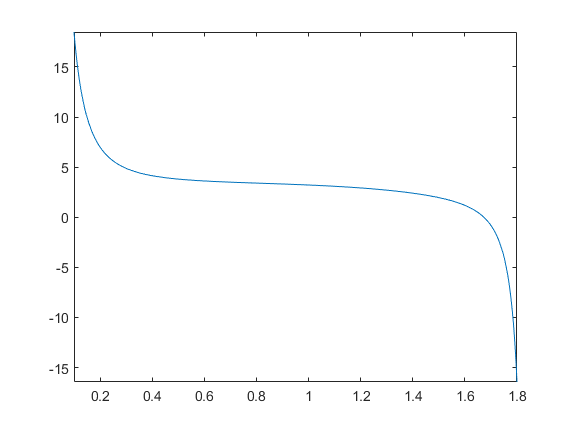

figure
fplot(simplify(diff(fDeltaMaxsubs-fDeltaMinsubs,c)),[0.1,3.6/2])

xlabel('Radius (mm)')
ylabel('Differentiated Tolerance Bound')